% 多元线性回归分析：加州房价预测
% 核心公式：Y = β0 + β1X1 + β2X2 + ... + βnXn + ε

% 支持中文显示
set(groot, 'DefaultTextFontName', 'Kaiti');
set(groot, 'DefaultAxesFontName', 'Kaiti');

california_df = readtable('california_housing.csv');
disp("前5行数据：");

前5行数据：


disp(head(california_df));

    MedInc    HouseAge    AveRooms    AveBedrms    Population    AveOccup    Latitude    Longitude    MedHouseVal
    ______    ________    ________    _________    __________    ________    ________    _________    ___________
    8.3252       41        6.9841       1.0238         322        2.5556      37.88       -122.23        4.526   
    8.3014       21        6.2381      0.97188        2401        2.1098      37.86       -122.22        3.585   
    7.2574       52        8.2881       1.0734         496        2.8023      37.85       -122.24        3.521   
    5.6431       52        5.8174       1.0731         558        2.5479      37.85       -122.25        3.413   
    3.8462       52        6.2819       1.0811         565        2.1815      37.85       -122.25        3.422   
    4.0368       52        4.7617       1.1036         413        2.1399      37.85       -122.25        2.697   
    3.6591       52        4.9319      0.95136        1094        2.1284      37.84     

disp("\n数据描述信息：");

\n数据描述信息：


summary(california_df)

Variables:
    MedInc: 20640×1 double
        Values:
            Min        0.4999 
            Median     3.5348 
            Max            15 
    HouseAge: 20640×1 double
        Values:
            Min           1   
            Median       29   
            Max          52   
    AveRooms: 20640×1 double
        Values:
            Min       0.84615 
            Median     5.2291 
            Max        141.91 
    AveBedrms: 20640×1 double
        Values:
            Min       0.33333 
            Median     1.0488 
            Max        34.067 
    Population: 20640×1 double
        Values:
            Min            3  
            Median      1166  
            Max        35682  
    AveOccup: 20640×1 double
        Values:
            Min       0.69231 
            Median     2.8181 
            Max        1243.3 
    Latitude: 20640×1 double
        Valu

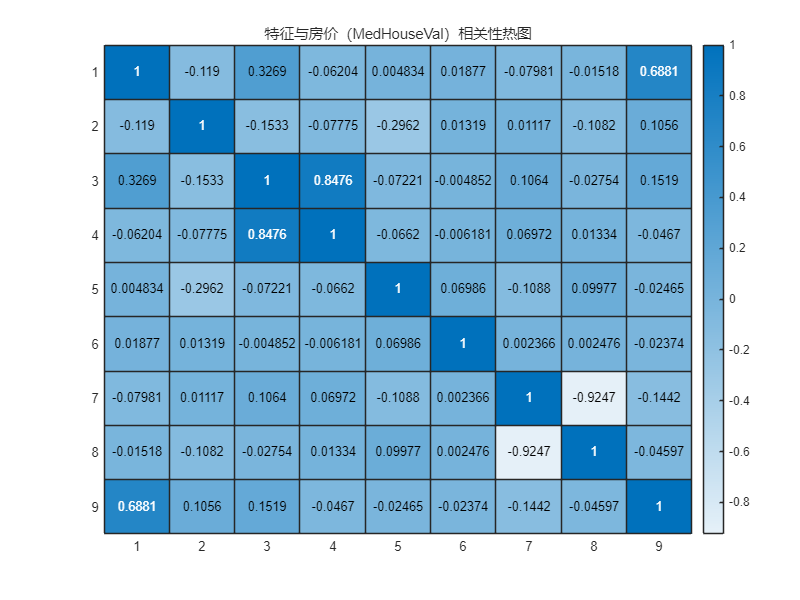

%% 热力图查看各变量与房价的关系
figure('Position', [100 100 800 600]);
corrMatrix = corr(table2array(california_df));
heatmap(corrMatrix, 'Title', '特征与房价（MedHouseVal）相关性热图');
colorbar;

features = {'MedInc', 'AveRooms', 'HouseAge', 'AveBedrms', ...
            'Population', 'AveOccup', 'Latitude', 'Longitude'};
X = table2array(california_df(:, features));  % 输入变量
y = california_df.MedHouseVal;  % 目标变量（房价）

%% 特征标准化处理
X_scaled = zscore(X);  % MATLAB中zscore实现标准化

%% 建立并训练多元线性回归模型
model = fitlm(X_scaled, y);
predictions = predict(model, X_scaled);

%% 模型预测与评估
mse = mean((y - predictions).^2);  % 均方误差
rmse = sqrt(mse);  % 均方根误差
r2 = model.Rsquared.Ordinary;  % 决定系数（拟合优度）

% 输出结果
disp("模型系数（β）：");

模型系数（β）：


disp(model.Coefficients.Estimate(2:end)');  % 排除截距项

    0.8296   -0.2655    0.1188    0.3057   -0.0045   -0.0393   -0.8999   -0.8706


disp("模型截距（β0）：");

模型截距（β0）：


disp(model.Coefficients.Estimate(1));

    2.0686


disp("均方误差 MSE：" + mse);

均方误差 MSE：0.52432


disp("均方根误差 RMSE：" + rmse);

均方根误差 RMSE：0.7241


disp("决定系数 R²：" + r2);

决定系数 R²：0.60623


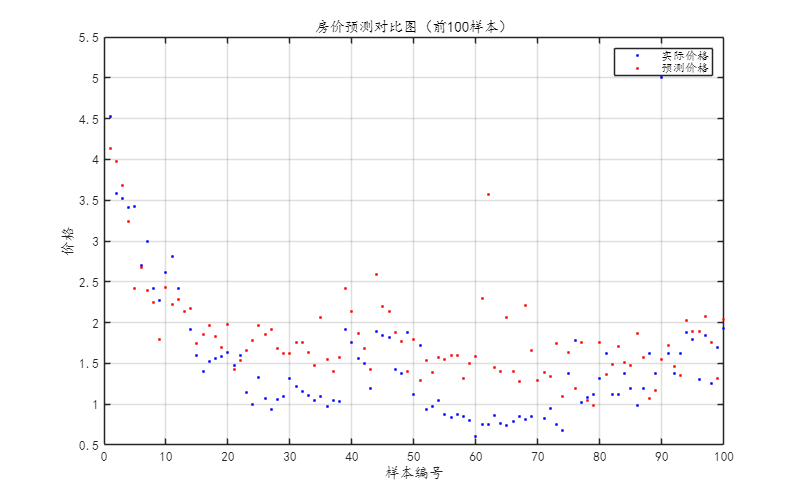

%% 预测结果与真实房价对比图
figure('Position', [100 100 800 500]);
plot(1:min(100, length(y)), y(1:min(100, length(y))), 'b.', ...
     1:min(100, length(y)), predictions(1:min(100, length(y))), 'r.');
title("房价预测对比图（前100样本）");
xlabel("样本编号");
ylabel("价格");
legend('实际价格', '预测价格');
grid on;

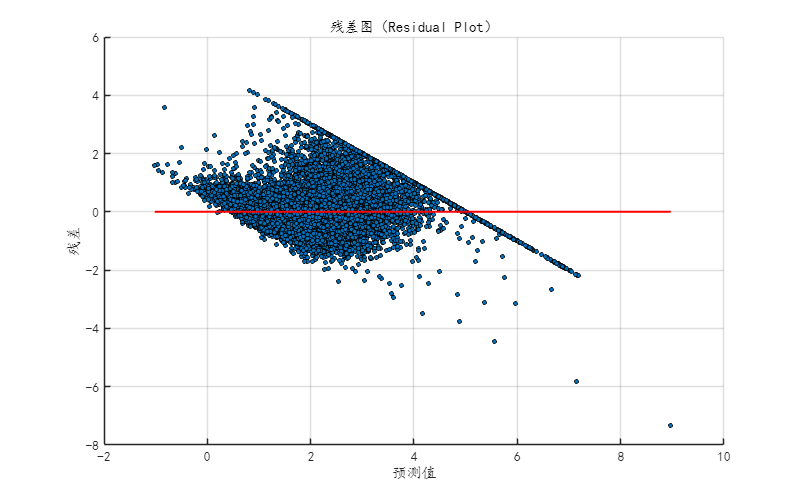

%% 扩展任务1：残差分析
residuals = y - predictions;  % 残差 = 实际值 - 预测值
figure('Position', [100 100 800 500]);
scatter(predictions, residuals, 10, 'filled', 'MarkerEdgeColor', 'k');
hold on;
plot([min(predictions), max(predictions)], [0, 0], 'r-', 'LineWidth', 1.5);
title("残差图（Residual Plot）");
xlabel("预测值");
ylabel("残差");
grid on;
hold off;

%% 扩展任务2：交叉验证
k = 5;  % 5折交叉验证
cv = cvpartition(length(y), 'KFold', k);
r2_scores = zeros(k, 1);

for i = 1:k
    trainIdx = cv.training(i);
    testIdx = cv.test(i);
    model_cv = fitlm(X_scaled(trainIdx, :), y(trainIdx));
    y_pred = predict(model_cv, X_scaled(testIdx, :));
    r2_scores(i) = model_cv.Rsquared.Ordinary;
end

disp("5折交叉验证 R² 分数：");

5折交叉验证 R² 分数：


disp(r2_scores');

    0.5982    0.6081    0.6115    0.6108    0.6032


disp("平均交叉验证得分：" + mean(r2_scores));

平均交叉验证得分：0.60635


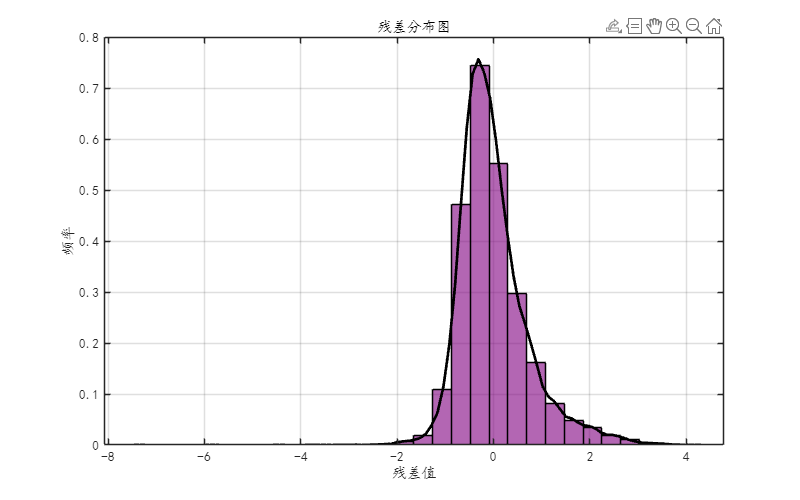

%% 扩展任务3：误差分布分析
figure('Position', [100 100 800 500]);
histogram(residuals, 30, 'Normalization', 'pdf', 'FaceColor', [0.5 0 0.5]);
hold on;
% 添加核密度估计
[kde, xi] = ksdensity(residuals);
plot(xi, kde, 'LineWidth', 2, 'Color', 'k');
title("残差分布图");
xlabel("残差值");
ylabel("频率");
grid on;
hold off;